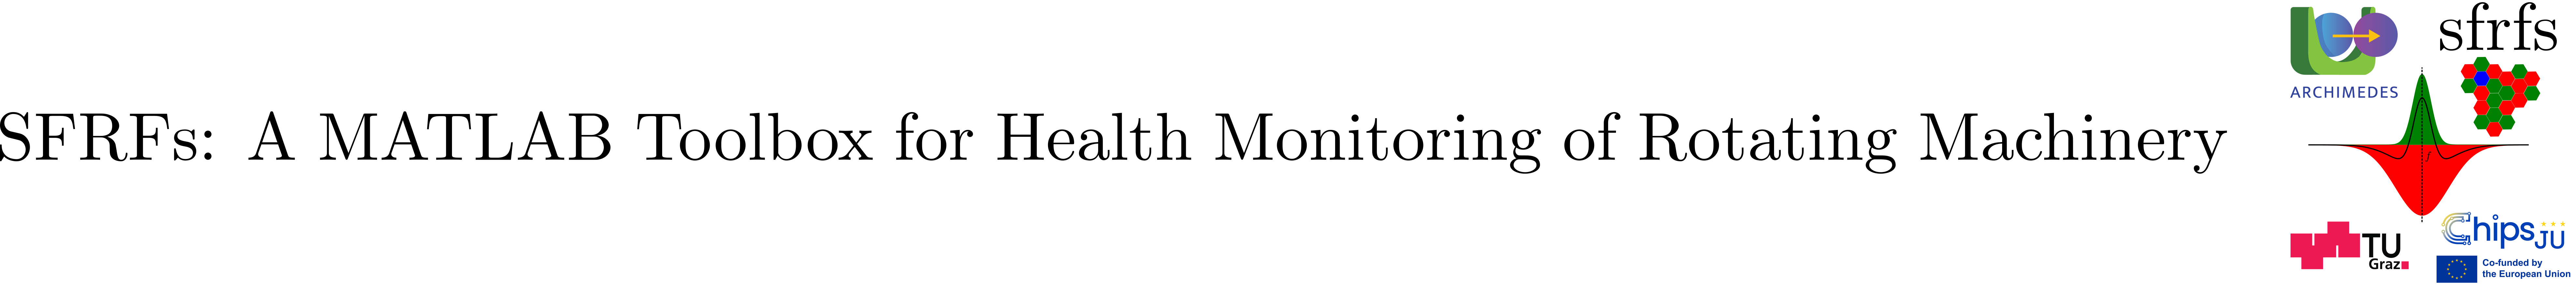

# RunToFailureSFRFsViewer

## Summary

`RunToFailureSFRFsViewer` is an embeddable visualization component for plotting a scalar SFRF trajectory over snapshots in a run-to-failure ensemble member.

## Description

This viewer delegates all computation to `CenterSurroundCompute.compute()`, then plots the returned SFRF vector over snapshot index.

Design:

- All computation is delegated to `CenterSurroundCompute.compute()`.

- The viewer only renders the returned SFRF vector.

Exploratory injection:

- `receptiveFieldResponseFunction` and `contrastMapping` are forwarded verbatim to the compute layer. If `contrastMapping` is empty, the compute layer applies its own default behavior (DoG).

### Properties

### Constructor

#### Syntax

- v = viz.RunToFailureSFRFsViewer(Name=Value, ...)

### Parameters (Name=Value)

### Methods

#### `renderSFRF` selection rules

Exactly one selection mechanism must be used:

- Row selection: `renderSFRF(row=...)`

- Semantic selection: `renderSFRF(faultType=..., selection=...)`

The semantic selection requires an `OperatingConditionSelection`.

#### `renderSFRF` parameters (Name=Value)

#### Note

Long type names and default function handles are split across lines in the table for layout clarity. Full type names and default implementations are specified in the Description and Examples sections.

### See also

[RFGFViewer](matlab:open('./RFGFViewer.mlx')), [RunToFailureRFGFsFilteredSpectraViewer](matlab:open('./RunToFailureRFGFsFilteredSpectraViewer.mlx')), [CenterSurroundCompute](matlab:open('./CenterSurroundCompute.mlx')), [ReceptiveFieldResponseFunctions](matlab:open('./ReceptiveFieldGainFunctions.mlx')), [ContrastMappings](matlab:open('./ContrastMappings.mlx'))

## Example

%% RunToFailureSFRFsViewer: self-contained example (mock run-to-failure)
% This example:
% 1) Creates snapshot + operating-condition metadata
% 2) Builds bearing frequency bands and RFGFs
% 3) Creates a mock ensemble and runs FFTEnsembleProcessor
% 4) Reconfigures datastore to expose FFT columns
% 5) Reads the member table
% 6) Visualizes an SFRF over snapshots
% 7) Reconfigure datastore to expose new FFT columns
% 8) Viewer: SFRF over snapshots

% Seed random number generator
rng(0);

%% 1) Snapshot descriptor (XJTU-SY settings)
sp = ParametersSnapshot( ...
    samplingFrequency = 25600, ...
    duration = 1.28, ...
    stride = 60);

%% 2) Operating conditions (must match mock ensemble metadata)
speedsHz = [35; 37.5; 40];
loadsKN  = [12; 11; 10];
oc = OperatingConditions(speedsHz, loadsKN);

%% 3) Bearing geometry
bp = ParametersRollingBearings( ...
    numRollingElements = 8, ...
    ballDiameter = 7.92, ...
    pitchDiameter = 34.55, ...
    contactAngle = 0);

%% 4) Shared SFRF parameters (same for all fault types)
sharedParams = SFRFsParameters.buildSFRFsParameters( ...
    order = 0, ...
    numSidebands = 2, ...
    numHarmonics = 10, ...
    centerMask = GaussianMaskParameters( ...
        bandwidth = 4, ...
        sigmaRule = 1.0253), ...
    surroundMask = GaussianMaskParameters( ...
        bandwidth = 12, ...
        sigmaRule = 0.8905), ...
    inhibitionFactor = 0.8647);

sfrfsParams = SFRFsParametersRollingBearings( ...
    SameForAllFaultTypes = sharedParams);

%% 5) Frequency bands + gain functions (RFGFs)
bfb = BearingFrequencyBands( ...
    bearingParams = bp, ...
    sfrfsParams = sfrfsParams, ...
    operatingConditions = oc);

bfb.computeBands();

rfgfs = ReceptiveFieldGainFunctions(bfb);
f = sp.getFrequencyDomain();
rfgfs.computeGainFunctions(f);

%% 6) Mock ensemble + broker + FFTEnsembleProcessor
rng(0);

temporalCols = { ...
    "HorizontalAcceleration", ...
    "VerticalAcceleration"};

nSamples = sp.getTotalSamples();

ensembleMock = EnsembleMock( ...
    numMembers = 1, ...
    nSamples = nSamples, ...
    temporalSnapshotColumns = temporalCols, ...
    speeds = speedsHz, ...
    loads = loadsKN);

ensembleMock.prepare();
clean = onCleanup(@() ensembleMock.cleanup());

broker = EnsembleBroker( ...
    ensembleObject = ensembleMock.fileEnsembleDS, ...
    getFilesFunction = @(obj) obj.Files, ...
    temporalSnapshotColumns = temporalCols);

processor = FFTEnsembleProcessor( ...
    numWorkers = 2, ...
    ensemble = broker);

processor.process();

%% 7) Reconfigure datastore to expose new FFT columns
fftCols = string(cellfun( ...
    @(c) broker.mapToSpectralColumn(c), ...
    temporalCols, ...
    UniformOutput = false)).';

ensName = "mock-ensemble";

EnsembleDatastoreRegistry.addEnsemble( ...
    name = ensName, ...
    datastore = broker.ensemble);

ensemble = EnsembleDatastoreRegistry.reconfigureEnsemble( ...
    name = ensName, ...
    DataVariables = unique([ ...
        broker.ensemble.DataVariables(:); fftCols(:)], "stable"), ...
    SelectedVariables = unique([ ...
        broker.ensemble.SelectedVariables(:); fftCols(:)], "stable"));

reset(ensemble);
member = read(ensemble);

%% 8) Viewer: SFRF over snapshots
v = viz.RunToFailureSFRFsViewer( ...
    memberTable = member, ...
    snapshotParameters = sp, ...
    rfgfs = rfgfs);

sel = OperatingConditionSelection(speed = 35, load = 12);
ft = SFRFsParametersRollingBearings.OUTER_RACE_FAULT_TYPE_NAME;

specCol = broker.mapToSpectralColumn("HorizontalAcceleration");

% Integrates the absolute spectrum as RFRF
rf = ReceptiveFieldResponseFunctions.integralAbs();

ax = v.renderSFRF( ...
    spectralColumn = specCol, ...
    faultType = ft, ...
    selection = sel, ...
    receptiveFieldResponseFunction = rf, ...
    titleText = "Run-to-failure SFRF (outer race, 35 Hz, 12 kN)");

xlabel(ax, "Snapshot index");
ylabel(ax, "SFRF value");

## API documentation

### MATLAB help

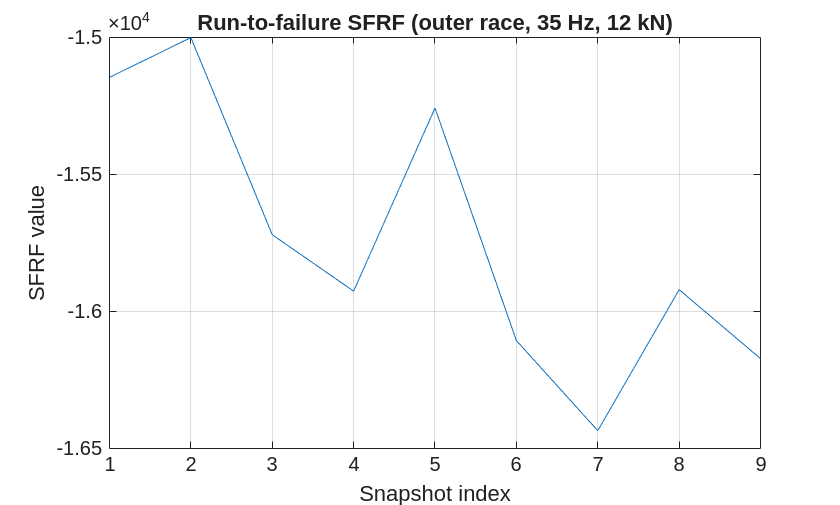

 RunToFailureSFRFsViewer  Visualize SFRFs over snapshots (run-to-failure).
 
  Design:
    - All computation is delegated to CenterSurroundCompute.compute().
    - This viewer only plots the returned SFRF vector over snapshots.
 
  Exploratory injection:
    - receptiveFieldResponseFunction and contrastMapping are forwarded
      verbatim to the compute layer, which defines defaults when empty.

    Documentation for viz.RunToFailureSFRFsViewer



help viz.RunToFailureSFRFsViewer

## Source code

The source of the class can be found in [RunToFailureSFRFsViewer](matlab:open('../../+viz/RunToFailureSFRFsViewer.m')).

## How to cite this work

Muñoz Gutiérrez, Stan, & Wotawa, Franz (2025). SFRFs: A MATLAB Toolbox for Health Monitoring of Rotating Machinery. Zenodo. DOI: [10.5281/zenodo.17631784](http://10.0.20.161/zenodo.17631784).

## References

- [1] Stan Muñoz Gutiérrez and Franz Wotawa. Optimized Spectral Fault Receptive Fields for Diagnosis-Informed Prognosis. In 36th International Conference on Principles of Diagnosis and Resilient Systems (DX 2025). Open Access Series in Informatics (OASIcs), Volume 136, pp. 9:1-9:20, Schloss Dagstuhl – Leibniz-Zentrum für Informatik (2025) [DOI:10.4230/OASIcs.DX.2025.9](https://doi.org/10.4230/OASIcs.DX.2025.9).

- [2] Biao Wang, Yaguo Lei, Naipeng Li, Ningbo Li, “A Hybrid Prognostics Approach for Estimating Remaining Useful Life of Rolling Element Bearings”, IEEE Transactions on Reliability, pp. 1-12, 2018. [DOI: 10.1109/TR.2018.2882682](https://doi.org/10.1109/TR.2018.2882682).